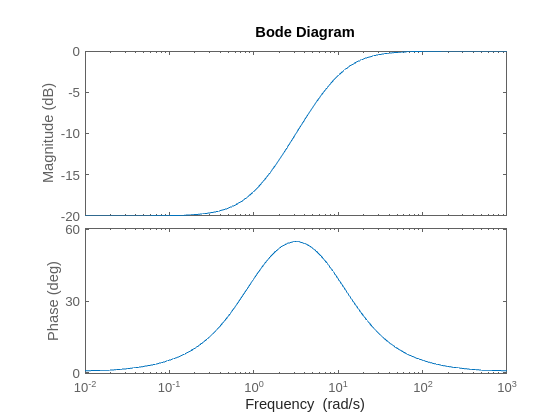

s = tf('s');
bode((s+1)/(s+10));

omega = 10;
zeta = 0.5;
H = omega^2 / (s*(s+2*zeta*omega))

H =
 
     100
  ----------
  s^2 + 10 s
 
Continuous-time transfer function.
Model Properties


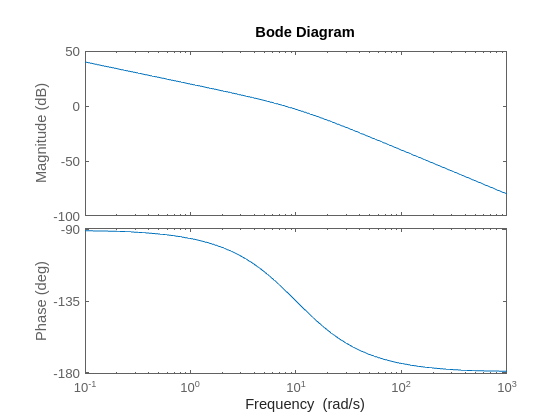

bode(H)

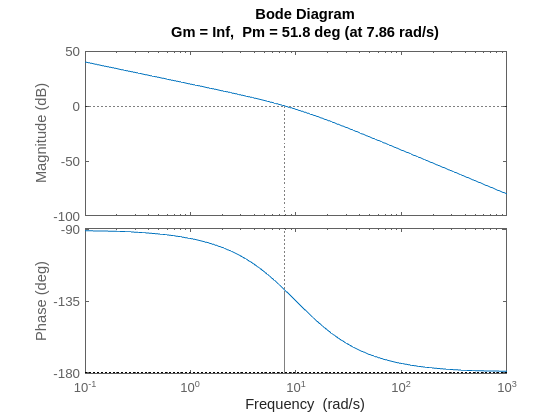

margin(H)

# Exercise 7.2

Consider a third order system:

clc;
s = tf('s');
G = (50*10^3) / (s*(s+10)*(s+50))

G =
 
         50000
  --------------------
  s^3 + 60 s^2 + 500 s
 
Continuous-time transfer function.
Model Properties


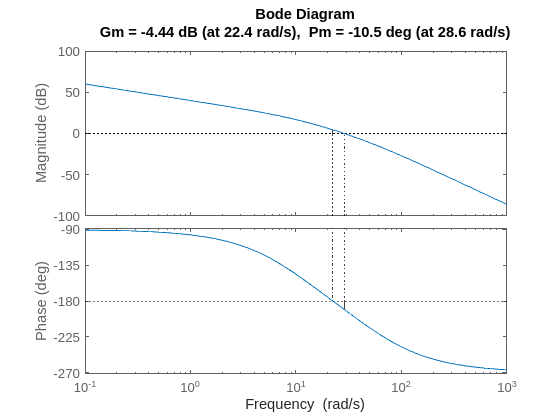

margin(G)

Design a LEAD compensator to make Phase Margin > 50 deg and bandwith > 20 rad/s

Lead compensator' design: 

Determine K so open loop crossover is factor 2 below closed loop bandwith:

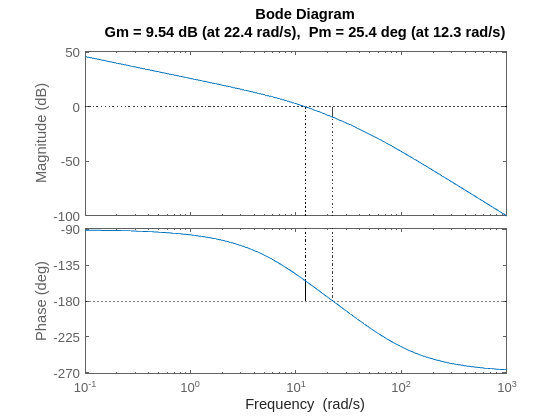

K = 0.2;
% Evaluate phase margin of uncompensated system with K parameter
margin(K*G)

So we need about 25 + 10 degrees more phase margin to satisfy the requirements.

Determine alpha from this:

phi_max = 50+10-25.4;
alpha = (1-sind(phi_max)) / (1+sind(phi_max))

alpha = 0.2756

Determine T like:

omegamax = 12.3; %Crossover frequency
T = 1/(omegamax * sqrt(alpha))

T = 0.1549

Lead_comp = K * ((T*s+1)/(alpha*T*s+1))

Lead_comp =
 
  0.03097 s + 0.2
  ---------------
   0.04268 s + 1
 
Continuous-time transfer function.
Model Properties


Draw the compensated frequency response and check gain and phase margins:

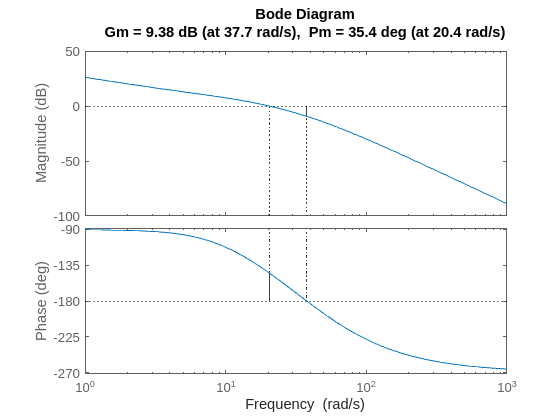

H = Lead_comp * G;
margin(H) %Not good enough

K1 = 0.1;
alpha1 = alpha;
T1 = T;
Lead_comp1 = K1 * ((T1*s+1)/(alpha1*T1*s+1))

Lead_comp1 =
 
  0.01549 s + 0.1
  ---------------
   0.04268 s + 1
 
Continuous-time transfer function.
Model Properties


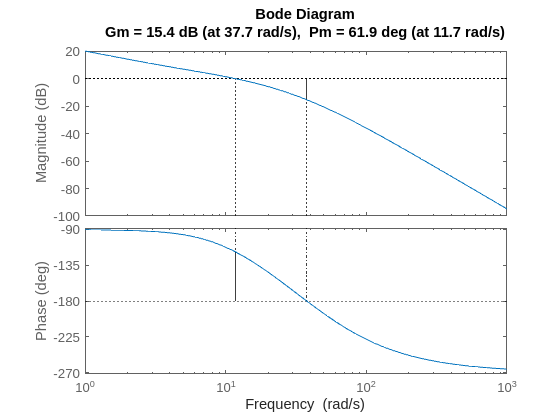

H1 = Lead_comp1 * G;
margin(H1) % After a few iterations, it is now good.